`Projektarbeit Bildgebung in der Therapie WiSe2024/2025`

`Code für Deep Learning`

`Abgabe von Melanie Hartmann und Sophie Scholtyssek`

Der folgende Code wurde unter Verwendung einer bereitgestellten Vorlage entwickelt, die auf den Inhalten des Moduls *Deep Learning in der Medizin* basiert. Das Skript lehnt sich an den Code *Brain-MRI-Age-Classification-using-Deep-Learning* von MATLAB an, der uns zur Verfügung gestellt wurde. Dieser ist unter folgendem Link zu finden: 

[Brain-MRI-Age-Classification-using-Deep-Learning - File Exchange - MATLAB Central](https://de.mathworks.com/matlabcentral/fileexchange/74941-brain-mri-age-classification-using-deep-learning).

Das Schließen aller Datein ist von Vorteil um sicherzustellen, dass das System eigenständig durchläuft und keine voreingestellten Variablen übernimmt, sondern die gesamte Auswertung auf diesem Skript basiert.

close all;
clear all;

Aufrufen des Hauptordner der Bilddaten

mainFolder = 'linear_array';

Unterteilung in Nadel und keine Nadel

with_needle_Folder = fullfile(mainFolder, 'with_needle');
wo_needle_Folder = fullfile(mainFolder, 'wo_needle');
with_stick_Folder = fullfile(mainFolder, 'with_stick');

Um die Bilder vergleichen zu können, sollten die Bilder gleich skaliert werden. Festlegung einer skalierten Bildgröße

targetSize = [224 224];

Erstellen eines Ordners für skalierte Daten

scaledFolder = fullfile(mainFolder, 'ScaledData');
if ~exist(scaledFolder, 'dir'),
    mkdir(scaledFolder); 
end

Erstellung von Zielunterordner für die zwei Kategorien: mit Nadel und ohne Nadel

folders = {'with_needle', 'wo_needle'};
for i = 1:numel(folders)
    targetSubfolder = fullfile(scaledFolder, folders{i});
    if ~exist(targetSubfolder, 'dir'), 
        mkdir(targetSubfolder); 
    end
end

 Daten sammeln und skalieren

categories = {'with_needle', 'wo_needle'};

Erstellen einer Datentabelle um eine Übersicht der Daten zu haben

dataTable = table([], [], [], 'VariableNames', {'FileName', 'FilePath', 'Label'});

Verarbeitung aller  Bilder mit Nadel und Speicherung in der dataTable

needle_Files = dir(fullfile(with_needle_Folder, '*.png'));
for i = 1:length(needle_Files)
    originalPath = fullfile(needle_Files(i).folder, needle_Files(i).name);
    scaledPath = fullfile(scaledFolder, 'with_needle', needle_Files(i).name);
    img = imread(originalPath);
    % Konvertieren in 3-Kanal-Bild (falls notwendig)
    if size(img, 3) == 1
        img = cat(3, img, img, img);
    end
    imgResized = imresize(img, targetSize);
    imwrite(imgResized, scaledPath);
    dataTable = [dataTable; {needle_Files(i).name, scaledPath, 'with_needle'}];
end

Verarbeitung aller  Bilder ohne Nadel und Speicherung in der dataTable

wo_needle_Files = dir(fullfile(wo_needle_Folder, '*.png'));
for i = 1:length(wo_needle_Files)
    originalPath = fullfile(wo_needle_Files(i).folder, wo_needle_Files(i).name);
    scaledPath = fullfile(scaledFolder, 'wo_needle', wo_needle_Files(i).name);
    
    % Überprüfen, ob Datei existiert und nicht leer ist
    if ~isfile(originalPath)
        fprintf('Datei nicht gefunden oder ungültig: %s\n', originalPath);
        continue;
    end
    
    fileInfo = dir(originalPath);
    if fileInfo.bytes == 0
        fprintf('Leere Datei übersprungen: %s\n', originalPath);
        continue;
    end
    
    % Versuche, das Bild zu laden, fange Fehler ab
    try
        img = imread(originalPath);
    catch ME
        fprintf('Fehler beim Lesen von %s: %s\n', originalPath, ME.message);
        continue;
    end
    
    % Falls das Bild einen Alpha-Kanal hat, entferne ihn
    if size(img, 3) == 4
        img = img(:, :, 1:3);
    end
    
    % Falls das Bild 16-Bit ist, konvertiere es zu 8-Bit
    if isa(img, 'uint16')
        img = uint8(img / 256);
    end
    
    % Falls das Bild nur einen Kanal hat, konvertiere es zu RGB
    if size(img, 3) == 1
        img = cat(3, img, img, img);
    end
    
    % Bild skalieren und speichern
    imgResized = imresize(img, targetSize);
    imwrite(imgResized, scaledPath);
    dataTable = [dataTable; {wo_needle_Files(i).name, scaledPath, 'wo_needle'}];
end

Fehler beim Lesen von C:\Users\sophi\OneDrive\Dokumente\Uni\Master\1. Semester\Bildgebung in der Therapie\Codes_Bildgebung\linear_array\wo_needle\330.png: PNG library failed:
Read Error


Anzeige der Anzahl der Bilder für alle Kategorien

disp(['Insgesamt ' num2str(height(dataTable)) ' Bilder verarbeitet.']);

Insgesamt 611 Bilder verarbeitet.


disp(['Mit einer Nadel: ' num2str(sum(strcmp(dataTable.Label, 'with_needle')))]);

Mit einer Nadel: 281


disp(['Ohne Nadel: ' num2str(sum(strcmp(dataTable.Label, 'wo_needle')))]);

Ohne Nadel: 330


Labels als kategorische Variable festlegen

dataTable.Label = categorical(dataTable.Label);

Zufällige Reihenfolge der Tabelle erstellen mit randperm

dataTable = dataTable(randperm(height(dataTable)), :);

ImageDatastore erstellen

mriImgds = imageDatastore(dataTable.FilePath, 'Labels', dataTable.Label);

mriImgdsRand = shuffle(mriImgds);
mriImgdsExamples = splitEachLabel(mriImgdsRand,1,'randomized',true); % Select the firstmost image from the just-shuffled datastore for each age class
numLabels = length(mriImgdsExamples.Labels);

for ii=numLabels:-1:1
    [imgArray{ii},infoArray(ii)] = readimage(mriImgdsExamples,ii);
end
summary(mriImgds.Labels)

     with_needle      281 
     wo_needle        330 


Wir können diese zufällige Auswahl aus jedem Label anzeigen, um zu sehen, wie sie nebeneinander stehen:

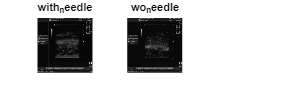

LabelArray = string(dataTable.Label);
LabelClasses = unique(LabelArray);
figure('Position',[10 10 500 150]);
tiledlayout(1,3,'Padding','none','TileSpacing','none');
for selCount=1:length(LabelClasses);
    idx = find(LabelClasses(selCount) == [infoArray.Label]);
    [~,fname] = fileparts(infoArray(idx).Filename);
    if startsWith(fname,'image2')
        img = imrotate(imgArray{idx},-180);
    else
        img = imgArray{idx};
    end
    nexttile;
    imshow(mat2gray(img));
    title(infoArray(idx).Label);
end

## Aufteilung in Trainings-, Validierungs- und Testdatensätze

Gemäß dieser Zeilen werden die Daten in Trainings-, Validierungs- und Testdatensätze unterschieden. Damit die gleiche Aufteilung gemäß der Untersuchung vorliegt, werden die Datensätze aus den Untersuchungen eingelesen. 

[trainImgs, testImgs] = splitEachLabel(mriImgds, 0.9, 'randomized');
[trainImgs, valImgs] = splitEachLabel(trainImgs, 0.85, 'randomized');
disp('Trainings-, Validierungs- und Testdatensätze erfolgreich erstellt.');

Trainings-, Validierungs- und Testdatensätze erfolgreich erstellt.


% load('workspace.mat', 'trainImgs');
% load ('workspace.mat', 'testImgs');
% load ('workspace.mat', 'valImgs');

Verwendung des vortrainierten Netzes Resnet-18.

netName = 'resnet18';
[net, classLabel] =imagePretrainedNetwork("resnet18");
netInputSize = net.Layers(1).InputSize;
inputImageSize = netInputSize(1:2);
img = imread('C:\Users\sophi\OneDrive\Dokumente\Uni\Master\1. Semester\Bildgebung in der Therapie\Bilder\needle_detection\needle_detection\needle_detection\resources\linear_array\ScaledData\with_needle\0.png');

Überprüfen der Anzahl der Kanäle

if size(img, 3) == 1
    % Graustufenbild in ein 3-Kanal-Bild umwandeln
    img = cat(3, img, img, img);
end


Konvertieren in Einzelpräzision (falls erforderlich)

img = im2single(img);
scores=predict(net, single(img));
imgLabel = scores2label(scores, classLabel);

Visualisierung der Bilder und der Vorhersage

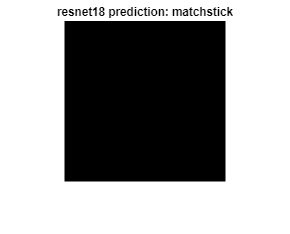

figure('Position',[10 10 200 200]);
imshow(img)
title([netName ' prediction: ' char(imgLabel)]);

**Hier findet nun eine Unterbrechnung statt -> **

**Verwendung von: deepNetworkDesigner("-v1")**

## Traings-Validierungsüberprüfung

load('workspace.mat', 'trainImgs');
load ('workspace.mat', 'testImgs');
load ('workspace.mat', 'valImgs');
load('workspace.mat', 'trainedNetwork_5')
mriNet = trainedNetwork_5;

load('workspace.mat','datastore_test')
load('workspace.mat','datastore_validation')
%datastore_test = augmentedImageDatastore(inputImageSize, testImgs, 'ColorPreprocessing', 'gray2rgb');
%datastore_validation =  augmentedImageDatastore(inputImageSize, valImgs, 'ColorPreprocessing', 'gray2rgb');

Klassifizieren der Bilder des Testdatensatzes mit Hilfe des trainierten Netzes. 

Verwenden der Variablen "classify" mit den entsprechenden Eingaben (trainiertes Netzwerk und Testdatensatz). Das liefert die Vorhersage (test_preds) der Lungenzuordnungen sowie die Konfidenz des Netzwerkes (scores) für jede Vorhersage.

%[test_preds,test_scores] = classify(mriNet, datastore_test);

Hier werden die zuvor bestimmten Variablen übergeben. 

load('workspace.mat', 'test_preds')
load('workspace.mat', 'test_scores')
accuracy = mean(test_preds==testImgs.Labels);


## Konfusionsmatrix und Sensitivität und Sezifität bestimmen

Erstellen der Konfusionsmatrix und Visualisierung

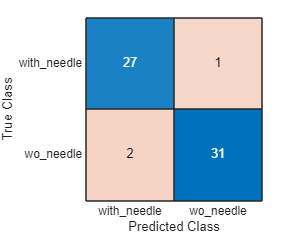

confMat = confusionchart(testImgs.Labels, test_preds);

 Berechnung der Konfusionsmatrix-Daten

confMatData = confusionmat(testImgs.Labels, test_preds);
TP = diag(confMatData);  % Wahre Positive
FP = sum(confMatData, 1)' - TP;  % Falsche Positive
FN = sum(confMatData, 2) - TP;  % Falsche Negative
TN = sum(confMatData(:)) - (FP + FN + TP);  % Wahre Negative

Berechnung der Sensitivität (Recall) für jede Klasse

sensitivity = TP ./ (TP + FN);


Berechnung der Spezifität für jede Klasse

specificity = TN ./ (TN + FP);

Anzeige der Ergebnisse

fprintf('Genauigkeit: %.2f%%\n', accuracy * 100);

Genauigkeit: 95.08%


classNames = {'mit Nadel', 'ohne Nadel'};  % Neue Klassennamen
for i = 1:length(sensitivity)
    fprintf('Klasse %s: Sensitivität = %.2f, Spezifität = %.2f\n', ...
        classNames{i}, sensitivity(i), specificity(i));
end

Klasse mit Nadel: Sensitivität = 0.96, Spezifität = 0.94
Klasse ohne Nadel: Sensitivität = 0.94, Spezifität = 0.96


Ansatz zur Positionsbestimmung der Nadel mit Deep-Learning mit GradCam

-> Das Bild zeigt in welchen Punkten es unterscheidet ob eine Nadel vorliegt oder nicht. Das ist gemäß der optischen Betrachtung nicht der Ort der Nadel und somit nicht erklärbar. Hier müsste noch eine Überarbeitung stattfinden. 

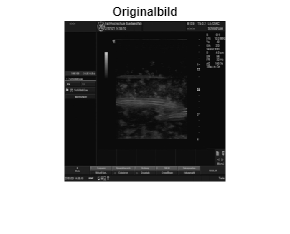

% Lade das trainierte Modell
load('workspace.mat', 'mriNet');

% Lade ein Beispielbild aus dem Testdatensatz
img = readimage(testImgs, 25);
img = im2single(img);  % Konvertiere das Bild in single-Format

% Falls das Bild Graustufen ist, in RGB umwandeln
if size(img, 3) == 1
    img = cat(3, img, img, img);
end

% Bildgröße anpassen (sicherstellen, dass es single-Format hat)
img = imresize(img, [224, 224], 'bilinear'); 
img = im2single(img); % Erneute Konvertierung in single-Format (falls nötig)

% Reshape für das Netzwerk (4D-Array)
imgBatch = reshape(img, [224, 224, 3, 1]);

% Vorhersage mit dem trainierten Netzwerk
scores = predict(mriNet, imgBatch);
[~, predLabelIdx] = max(scores); % Index der vorhergesagten Klasse

% Berechne Grad-CAM
map = gradCAM(mriNet, imgBatch, predLabelIdx, 'ExecutionEnvironment', 'cpu');

% Falls map nicht die Größe [224, 224] hat -> Resizing
if size(map,1) ~= 224 || size(map,2) ~= 224
    map = imresize(map, [224, 224], 'bilinear');
end

% Zeige das Originalbild
figure;
imshow(img);
title('Originalbild');

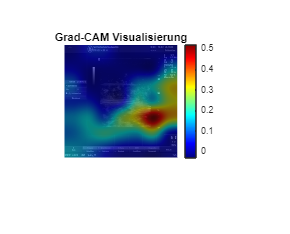


% Überlagere die Grad-CAM-Karte auf das Originalbild
figure;
imshow(img);
hold on;
heatmapOverlay = imagesc(map);
set(heatmapOverlay, 'AlphaData', 0.5); % Transparenz richtig setzen
colormap jet;
colorbar;
title('Grad-CAM Visualisierung');
hold off;